# SCEDC Data Access Tutorial

This tutorial will help walk you through how to access waveform, station, and event data from the Southern California Earthquake Data Center (SCEDC).

SCEDC does not currently offer its own tools for data access from Matlab; however, irisFetch can be used for access. For documentation and to download irisFetch, please see: [http://ds.iris.edu/ds/nodes/dmc/software/downloads/irisFetch.m/2-0-12/manual/](http://ds.iris.edu/ds/nodes/dmc/software/downloads/irisFetch.m/2-0-12/manual/)

Another useful tool for working with seismic data in Matlab is the GISMO toolbox. We're working to get direct access to SCEDC from GISMO, although this is not currently possible. For ore information on GISMO, see: [https://geoscience-community-codes.github.io/GISMO/](https://geoscience-community-codes.github.io/GISMO/)

Note: This tutorial was written using Matlab 2021b. Other versions may have varying degrees of compatibility.

## Retrieving Events from the SCSN Catalog

We'll start by getting a few events from the Southern California Seismic Network catalog. Let's look at the Jan. 2023 M4.2 near Malibu Beach and the aftershocks. We can specify CI as the contributor to only retrieve SCSN events, and we can also specify where to get the data from.

* Note: I was having trouble trying to use the NEIC or SCEDC URLs. This may depend on the version of Java you are using and whether it supports the secure https.

% Set up some parameters for reuse
search_area = [33.7,34.1,-119,-118.1]; % lat min & max, lon min & max
startt = '2023-01-25 10:00';
endt = '2023-01-25 19:00';

% Query the event catalog - currently getting a java error
%cat = irisFetch.Events('startTime',startt,'endTime',endt,'boxcoordinates',search_area,...
%    'BASEURL','https://service.scedc.caltech.edu/fdsnws/event/1/');%'http://service.iris.edu/fdsnws/event/1/');%'https://earthquake.usgs.gov/fdsnws/event/1/');%

% to query the CI catalog via ComCat or IRIS
cat = irisFetch.Events('contributor','ci','startTime',startt,'endTime',endt,'boxcoordinates',search_area,...
    'BASEURL','https://service.iris.edu/fdsnws/event/1/');%'https://earthquake.usgs.gov/fdsnws/event/1/');%

fetching...


7 events found *************

parsing into MATLAB structures


This query returns a structure with the event information. You can use the fieldnames() function to see which fields are available. Note: not all fields may have information in them.

fieldnames(cat)

ans = 15×1 cell array
    {'Type'                   }
    {'FlinnEngdahlRegionCode' }
    {'FlinnEngdahlRegionName' }
    {'PreferredTime'          }
    {'PreferredLatitude'      }
    {'PreferredLongitude'     }
    {'PreferredDepth'         }
    {'PreferredMagnitudeType' }
    {'PreferredMagnitudeValue'}
    {'PreferredOrigin'        }
    {'Origins'                }
    {'PreferredMagnitude'     }
    {'Magnitudes'             }
    {'Picks'                  }
    {'PublicId'               }


Let's map the events to see the distribution and locations.

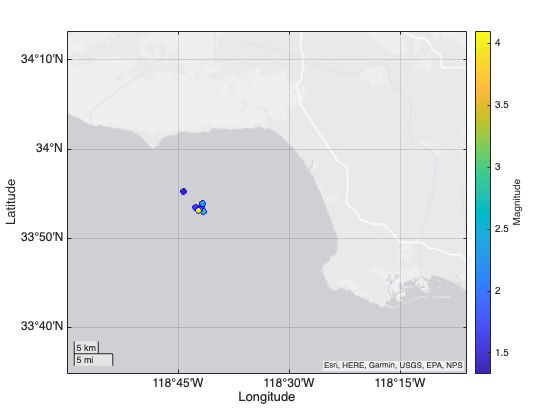

% Make event plot
if license('test', 'image_toolbox') % use mapping toolbox if available
    figure;
    geoscatter(extractfield(cat,'PreferredLatitude'),extractfield(cat,'PreferredLongitude'),36,...
        extractfield(cat,'PreferredMagnitudeValue'),'filled','o','MarkerEdgeColor','b');
    geolimits(search_area(1:2),search_area(3:4));

else % If no mapping toolbox, just make scatter plot
    figure;
    scatter(extractfield(cat,'PreferredLongitude'),extractfield(cat,'PreferredLatitude'),36,...
        extractfield(cat,'PreferredMagnitudeValue'),'filled','o','MarkerEdgeColor','b');

end

c = colorbar('eastoutside');
c.Label.String = 'Magnitude';
set(gca,'fontsize',12)
box on;

## Finding Station Data

Next we'll find a station near the earthquakes to get waveforms for. The SCSN network code is "CI", and we'll only search for the broad-band (HH) and strong motion (HN) channels, using the '?' wildcard to get all vertical and horizontal channels. The first and second '*' are wildcards for station and location, respectively. Once again, we need to specify the URL to query the SCEDC database.

% Make station query
sta_list = irisFetch.Stations('station','CI','*','*','HH?,HN?','boxcoordinates',search_area,...
    'StartBefore',startt,'EndAfter',endt,'BASEURL','https://service.scedc.caltech.edu/fdsnws/station/1/');

disp([num2str(length(sta_list)),' stations were found.']);

24 stations were found.


This query retrieves a structure with information about the stations that met our search criteria. Most of the fields (all listed after 'EndDate') are empty. To get more information about the channels available for these stations, we can do a channel search.

% Make list of stations from previous search
sta_text = '';
for s = 1:(length(sta_list)-1)
    sta_text = strcat(sta_text,sta_list(s).StationCode,','); 
end
sta_text = strcat(sta_text,sta_list(s+1).StationCode); 

% Make channel query
cha_list = irisFetch.Channels('channel','CI',sta_text,'*','HH?,HN?','StartBefore',startt,...
    'EndAfter',endt,'BASEURL','https://service.scedc.caltech.edu/fdsnws/station/1/');

disp([num2str(length(cha_list)),' channels were found.']);

162 channels were found.


This query returns a structure of channel information, including the instrument response. A closer inspection shows a field named 'Type" that specifies whether the data is triggered (blank is continuous). Let's remove those from our list.

% Remove triggered channels
cha_list(strcmp({cha_list.Type},'[]')==0) = [];

disp([num2str(length(cha_list)),' continuous channels are available.']);

60 continuous channels are available.


Let's plot the stations on a map with the events, then we can choose which ones to get waveforms from.

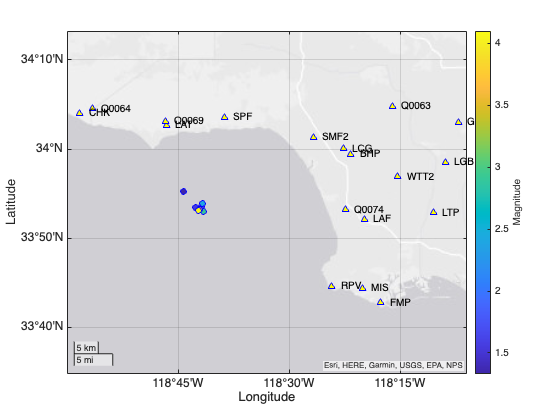

% Get list of stations with continuous channels
good_sta = unique(extractfield(cha_list,'StationCode'));

sta_coords = nan(length(good_sta),2);
for k = 1:length(good_sta)
    sta_coords(k,1:2) = [sta_list(strcmp(extractfield(sta_list,'StationCode'),good_sta{k})).Latitude,...
        sta_list(strcmp(extractfield(sta_list,'StationCode'),good_sta{k})).Longitude];
end

% Make map of events and stations

if license('test', 'image_toolbox') % use mapping toolbox if available
    figure;

    % plot stations
    geoscatter(sta_coords(:,1),sta_coords(:,2),36,'filled','^','MarkerEdgeColor','b','MarkerFaceColor','y');
    geolimits(search_area(1:2),search_area(3:4));
    hold on;
    text(sta_coords(:,1),sta_coords(:,2)+0.02,good_sta,'FontSize',10);

    % plot events
    geoscatter(extractfield(cat,'PreferredLatitude'),extractfield(cat,'PreferredLongitude'),36,...
        extractfield(cat,'PreferredMagnitudeValue'),'filled','o','MarkerEdgeColor','b');

else % If no mapping toolbox, just make scatter plot
    figure;

    % plot stations
    scatter(sta_coords(:,2),sta_coords(:,1),36,'filled','^','MarkerEdgeColor','b','MarkerFaceColor','y');
    hold on;
    text(sta_coords(:,2)+0.02,sta_coords(:,1),good_sta,'FontSize',10);
    
    % plot events
    scatter(extractfield(cat,'PreferredLongitude'),extractfield(cat,'PreferredLatitude'),36,...
        extractfield(cat,'PreferredMagnitudeValue'),'filled','o','MarkerEdgeColor','b');
end

c = colorbar('eastoutside');
c.Label.String = 'Magnitude';
set(gca,'fontsize',12)
box on;

## Accessing Wavform Data (irisFetch)

Waveforms can be retrieved with the Traces method of irisFetch. Note that you need to specify the SCEDC service for querying. We'll examine some waveforms for the M4.2 mainshock.

% Find mainshock index in catalog
[~,ms_ind] = max(extractfield(cat,'PreferredMagnitudeValue'));
ms_time = datenum(cat(ms_ind).PreferredTime); % get the event time and convert to datenum
wf_st = ms_time-(0.25/1440);
wf_end = ms_time+(1.75/1440);

% Send data request
sta = 'LAF';
cha = 'HH?,HN?';

wf = irisFetch.Traces('CI',sta,'*',cha,wf_st,wf_end,'http://service.scedc.caltech.edu','includepz');

edu.iris.dmc.service.NoDataFoundException: (204) No data found for: quality=B
CI LAF 2C HNE 2023-01-25T10:00:39.680 2023-01-25T10:02:39.680
	at edu.iris.dmc.service.WaveformService.fetch(WaveformService.java:116)
	at edu.iris.dmc.service.WaveformService.fetch(WaveformService.java:239)
	at edu.iris.dmc.service.WaveformService.fetch(WaveformService.java:292)
	at edu.iris.dmc.extensions.fetch.TraceData.fetchTraces(TraceData.java:394)
	at edu.iris.dmc.extensions.fetch.TraceData.fetchTraces(TraceData.java:192)
	at edu.iris.dmc.extensions.fetch.TraceData.fetchTraces(TraceData.java:137)
	at edu.iris.dmc.extensions.fetch.TraceData.fetchTraces(TraceData.java:102)
edu.iris.dmc.service.NoDataFoundException: (204) No data found for: quality=B
CI LAF 2C HNN 2023-01-25T10:00:39.680 2023-01-25T10:02:39.680
	at edu.iris.dmc.service.WaveformService.fetch(WaveformService.java:116)
	at edu.iris.dmc.service.WaveformService.fetch(WaveformService.java:239)
	at edu.iris.dmc.service.WaveformService.fetch(Wave

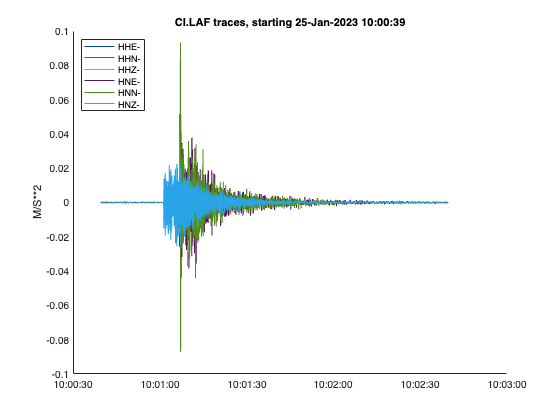

% Plot waveforms

colors=brighten(lines(numel(wf)),-0.33); % define line colors

figure;
for n=1:numel(wf)
  tr = wf(n);
  data=double(tr.data) ./ tr.sensitivity;    % scale the data
  data = detrend(data);
  sampletimes = linspace(tr.startTime,tr.endTime,tr.sampleCount);
  plot(sampletimes, data, 'color', colors(n,:));
  hold on;
end

hold off;
datetick;
ylabel(tr.sensitivityUnits); % assumes all units are the same 
title(['CI.',sta,' traces, starting ', datestr(wf(1).startTime)]); 
legend(strcat({wf.channel},'-',{wf.location}),'location','northwest');
box off
set(gca,'TickLength',[0 0])

## More Waveform Analysis with GISMO

Since we already have the waveform data, we can put it into GISMO to use its plotting and analysis tools.

% Put waveform data into waveform object

for w = 1:size(wf,2)
    ctag = ChannelTag(wf(w).network,wf(w).station,'--',wf(w).channel);
    wf_obj(w) = waveform(ctag,wf(w).sampleRate,startt,wf(w).data,'counts');
end

% Do a little pre-processing

wf_obj = fillgaps(wf_obj,0); % replace NaNs with 0s
wf_obj = demean(wf_obj); % remove mean

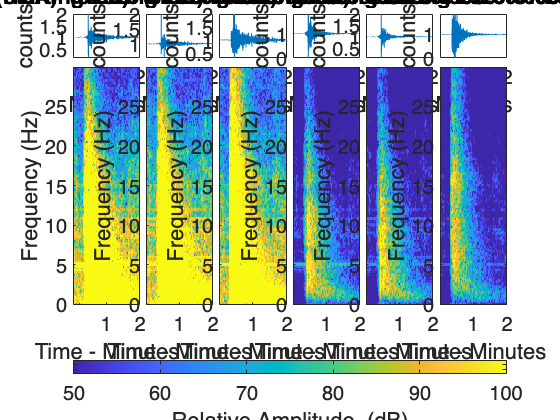

% Plot the spectrograms

figure;

specobj = spectralobject(512,(512*0.9),30,[50 100]); % nfft, overlap, max freq, dB range
specgram2(specobj,wf_obj,'xunit','minutes','fontsize',20,'innerLabels',false,'colormap','parula','specheight',0.65);

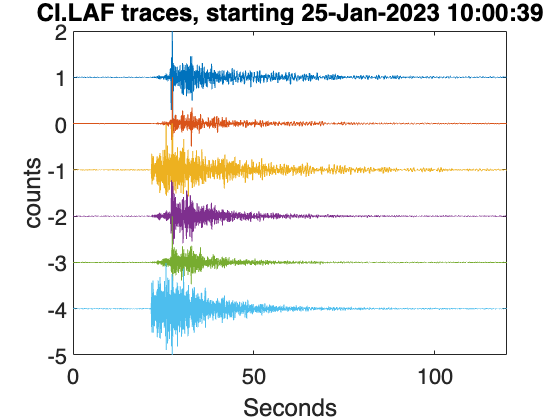


% try this for subplots if default doesn't work
% col = 3;
% r = 1;
% sp = 1;
% for i = 1:length(wf_obj)
% 
%     subplot(r,3,sp);
% 
%     specobj = spectralobject(512,(512*0.9),30,[50 100]); % nfft, overlap, max freq, dB range
%     specgram2(specobj,wf_obj(sp),'xunit','minutes','fontsize',20,'innerLabels',false,'colormap','parula','specheight',0.65);
%     
%     if i == 3 % move to next row
%         r = r+1;
%     end
% 
%     sp = sp+1;
% 
% end

% Apply a filter

f = filterobject('b', [1,15], 4); % high-pass filter
wf_obj = filtfilt(f,wf_obj);

% Plot the waveforms

plot(wf_obj,'autoscale',true,'fontsize',22);
set(gca,'xlim',[0,(wf_end-wf_st)*24*3600]);
title(['CI.',sta,' traces, starting ', datestr(wf(1).startTime)]);

Data can also be requested via IRIS using GISMO directly. Note that this may result in errors or missing data - it's not clear whether GISMO's use of the IRIS tools allows it to retrieve datat that's not stored at the IRIS DMC. Let's try it using the first aftershock.

% Set up parameters

as_time = datenum(cat(ms_ind-1).PreferredTime); % get the event time and convert to datenum (catalog is ordered with newest first)
wf_st = as_time-(0.25/1440);
wf_end = as_time+(1.75/1440);

ds = datasource('irisdmcws');
ctag = ChannelTag('CI',sta,'*',cha);

% Retrieve data
as_wf = waveform(ds, ctag, wf_st, wf_end);

Requesting Data from the DMC...
edu.iris.dmc.service.NoDataFoundException: (204) No data found for: quality=D
CI LAF 2C HNE 2023-01-25T10:03:18.360 2023-01-25T10:05:18.360
	at edu.iris.dmc.service.WaveformService.fetch(WaveformService.java:116)
	at edu.iris.dmc.service.WaveformService.fetch(WaveformService.java:239)
	at edu.iris.dmc.service.WaveformService.fetch(WaveformService.java:292)
	at edu.iris.dmc.extensions.fetch.TraceData.fetchTraces(TraceData.java:394)
	at edu.iris.dmc.extensions.fetch.TraceData.fetchTraces(TraceData.java:192)
	at edu.iris.dmc.extensions.fetch.TraceData.fetchTraces(TraceData.java:137)
	at edu.iris.dmc.extensions.fetch.TraceData.fetchTraces(TraceData.java:102)
edu.iris.dmc.service.NoDataFoundException: (204) No data found for: quality=D
CI LAF 2C HNN 2023-01-25T10:03:18.360 2023-01-25T10:05:18.360
	at edu.iris.dmc.service.WaveformService.fetch(WaveformService.java:116)
	at edu.iris.dmc.service.WaveformService.fetch(WaveformService.java:239)
	at edu.iris.dmc.se

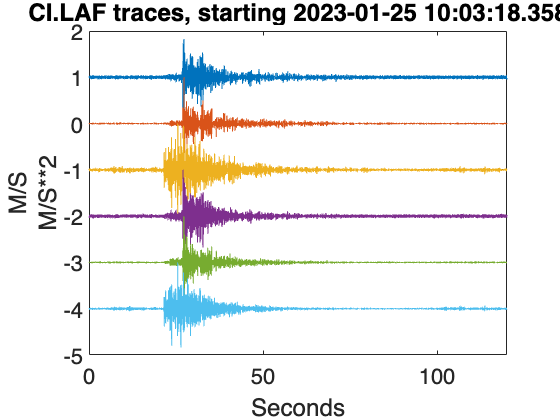

% Apply pre-processing

as_wf = fillgaps(as_wf,0); % replace NaNs with 0s
as_wf = demean(as_wf); % remove mean
f = filterobject('b', [2,15], 4); % high-pass filter
as_wf = filtfilt(f,as_wf);

% Plot the waveforms

plot(as_wf,'autoscale',true,'fontsize',22);
set(gca,'xlim',[0,(wf_end-wf_st)*24*3600]);
title(['CI.',sta,' traces, starting ', get(as_wf(1),'start_str')]);

----------

Created: 8 March 2023

Last updated: 17 March 2023

Author: Gabrielle Tepp